clear; close all; clc;
N = 3

N = 6

fc = 10;                  
omgc = 2*pi*fc;           
k = 0:(N-1);
poles = omgc * exp(1i*(pi/2 + (2*k+1)*pi/(2*N)));
disp('Computed Left-Half-Plane Poles:');

Computed Left-Half-Plane Poles:


for i = 1:length(poles)
    if abs(imag(poles(i))) < 1e-6
        % Treat as a real pole
        disp(['Pole ', num2str(i), ': Real = ', num2str(real(poles(i))), ' (Real Pole)']);
    else
        disp(['Pole ', num2str(i), ': Real = ', num2str(real(poles(i))), ', Imag = ', num2str(imag(poles(i)))]);
    end
end

Pole 1: Real = -16.2621, Imag = 60.6909
Pole 2: Real = -44.4288, Imag = 44.4288
Pole 3: Real = -60.6909, Imag = 16.2621
Pole 4: Real = -60.6909, Imag = -16.2621
Pole 5: Real = -44.4288, Imag = -44.4288
Pole 6: Real = -16.2621, Imag = -60.6909


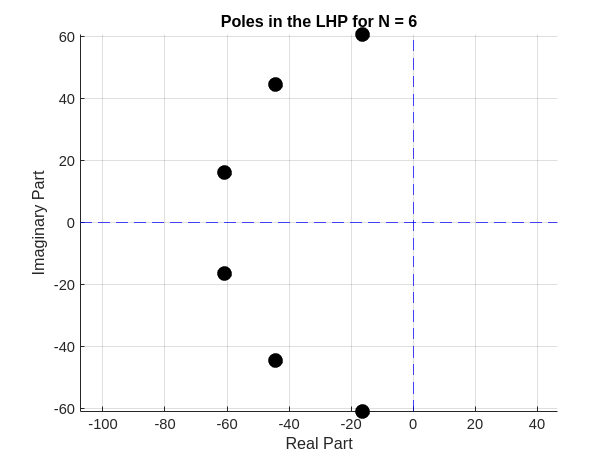


figure('Name','Butterworth Filter Poles','NumberTitle','off');
scatter(real(poles), imag(poles), 100, 'filled', 'k');
hold on; grid on; axis equal;
xline(0, '--b'); yline(0, '--b');
xlabel('Real Part'); ylabel('Imaginary Part');
title(['Poles in the LHP for N = ', num2str(N)]);

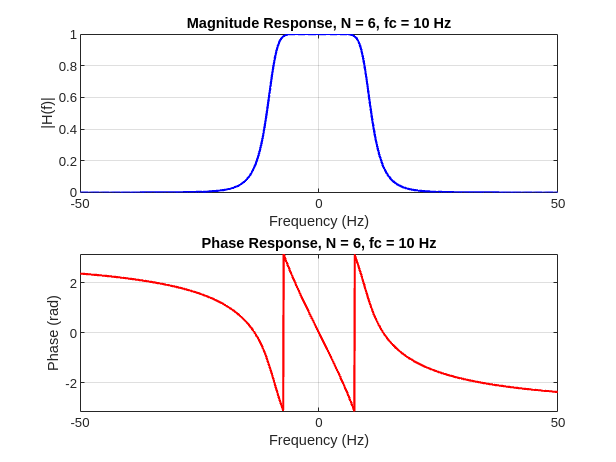


denom = poly(poles);        
gain  = omgc^N;             
sys   = tf(gain, real(denom));  

f = -50:0.1:50;             
omega = 2*pi*f;             
s = 1i * omega;             
H = gain ./ polyval(denom, s); 
Hmag = abs(H);              
Hphs = angle(H);           

figure('Name','Butterworth Lowpass Filter Frequency Response','NumberTitle','off');

subplot(2,1,1);
plot(f, Hmag, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)'); ylabel('|H(f)|');
title(['Magnitude Response, N = ', num2str(N), ', fc = ', num2str(fc), ' Hz']);
grid on;

subplot(2,1,2);
plot(f, Hphs, 'r', 'LineWidth', 1.5);
xlabel('Frequency (Hz)'); ylabel('Phase (rad)');
title(['Phase Response, N = ', num2str(N), ', fc = ', num2str(fc), ' Hz']);
grid on;
axis([-50 50 -pi pi]);

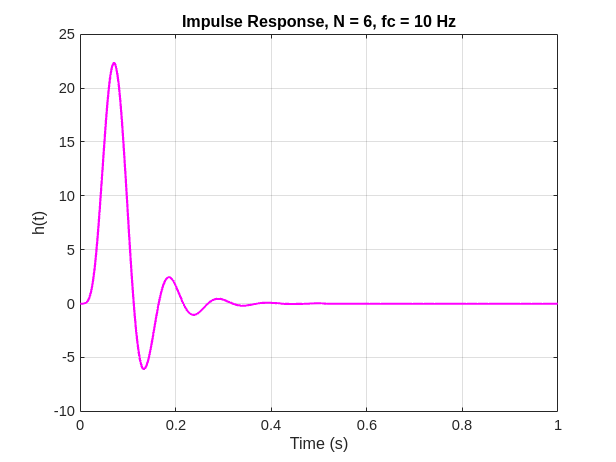


t_imp = linspace(0, 1, 1000);  
[h, t_out] = impulse(sys, t_imp);

figure('Name','Impulse Response of Butterworth LPF','NumberTitle','off');
plot(t_out, h, 'm', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('h(t)');
title(['Impulse Response, N = ', num2str(N), ', fc = ', num2str(fc), ' Hz']);
grid on;


disp('Generic Butterworth filter design complete.');

Generic Butterworth filter design complete.



function [mag, phs] = spectrums(zrs, pls, gain, omega)
    nz = length(zrs);
    np = length(pls);
    nomg = length(omega);
    s = 1j*omega;
    mag = ones(1, nomg);
    phs = zeros(1, nomg);
    
    for n = 1:nz
        mag = mag .* abs(s - zrs(n));
        phs = phs + angle(s - zrs(n));
    end
   
    for n = 1:np
        mag = mag ./ abs(s - pls(n));
        phs = phs - angle(s - pls(n));
    end
    mag = mag * gain;
    phs = wrapToPi(phs);
end



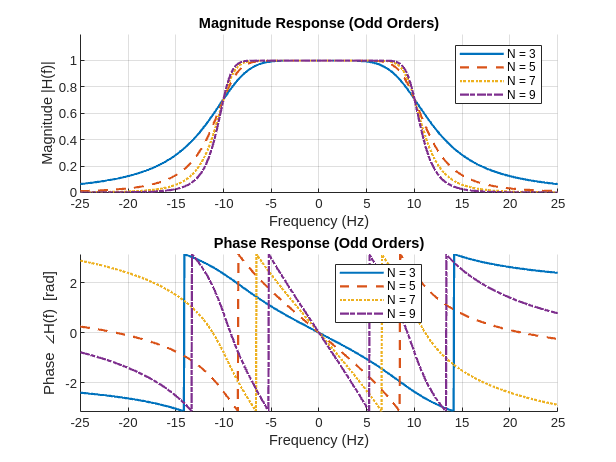



clear; close all; clc;

fc    = 10;         
omgc  = 2*pi*fc;    
f     = -25:0.05:25; 
omega = 2*pi*f;      

Nodd = [3, 5, 7, 9];
lineStyles = {'-','--',':','-.'};  
figure('Name','Butterworth LPF Response (Odd Orders)','NumberTitle','off');

subplot(2,1,1); hold on;
title('Magnitude Response (Odd Orders)');
xlabel('Frequency (Hz)'); ylabel('Magnitude |H(f)|');
axis([-25,25,0,1.2]);
grid on;

subplot(2,1,2); hold on;
title('Phase Response (Odd Orders)');
xlabel('Frequency (Hz)'); ylabel('Phase \angleH(f) [rad]');
axis([-25,25,-pi,pi]);
grid on;

legendOdd = cell(length(Nodd),1);

for idx = 1:length(Nodd)
    N = Nodd(idx);
    k_idx = ceil(N/2) : floor(3*N/2);  
    pls = omgc * exp(1i * pi * k_idx / N);
    [Hmag, Hphs] = spectrums([], pls, omgc^N, omega);
    subplot(2,1,1);
    plot(f, Hmag, lineStyles{idx}, 'LineWidth',1.5);
    
    subplot(2,1,2);
    plot(f, Hphs, lineStyles{idx}, 'LineWidth',1.5);
    
    legendOdd{idx} = ['N = ' num2str(N)];
end

subplot(2,1,1);
legend(legendOdd, 'Location','Best');
subplot(2,1,2);
legend(legendOdd, 'Location','Best');

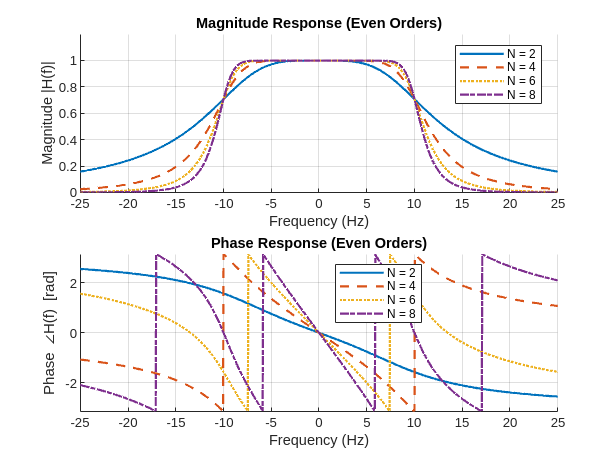

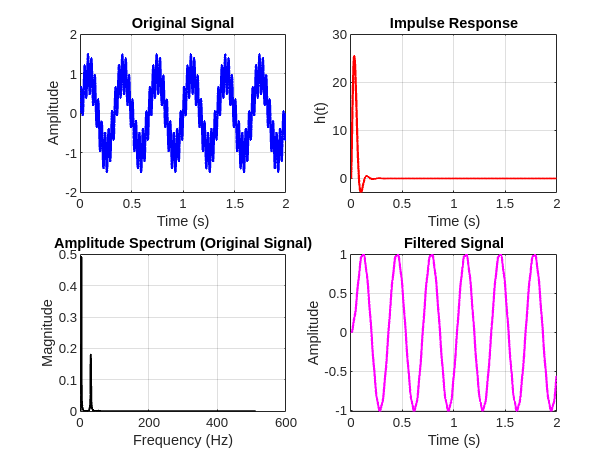

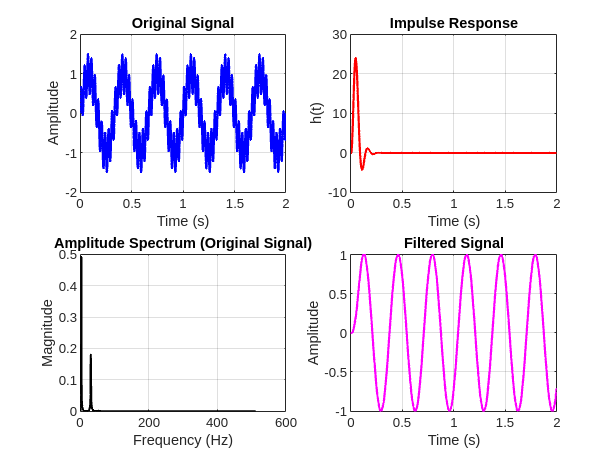

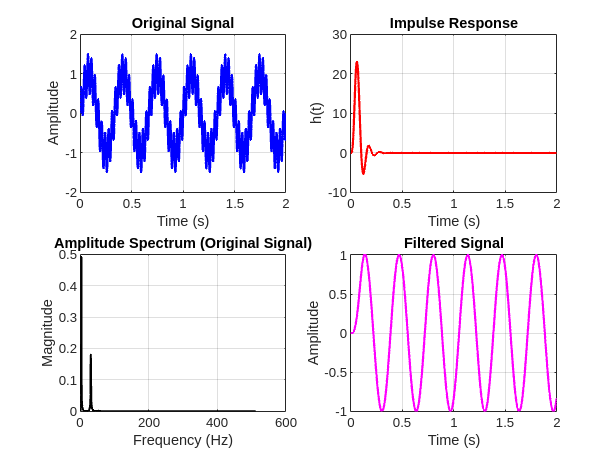

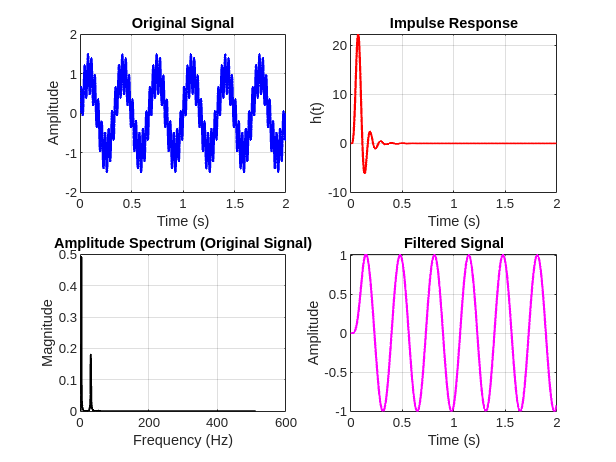

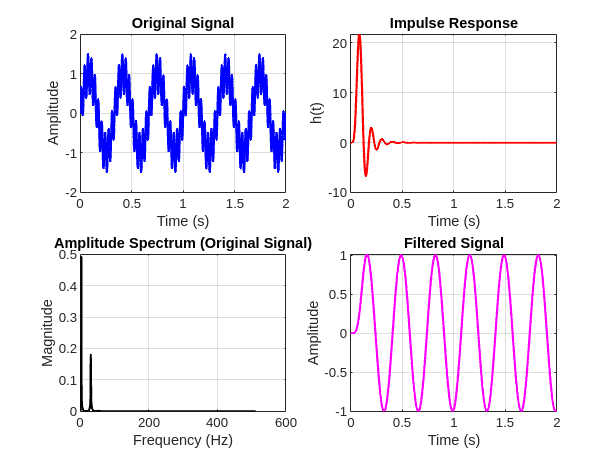


Neven = [2, 4, 6, 8];
lineStylesEven = {'-','--',':','-.'}; 
figure('Name','Butterworth LPF Response (Even Orders)','NumberTitle','off');

subplot(2,1,1); hold on;
title('Magnitude Response (Even Orders)');
xlabel('Frequency (Hz)'); ylabel('Magnitude |H(f)|');
axis([-25,25,0,1.2]);
grid on;

subplot(2,1,2); hold on;
title('Phase Response (Even Orders)');
xlabel('Frequency (Hz)'); ylabel('Phase \angleH(f) [rad]');
axis([-25,25,-pi,pi]);
grid on;

legendEven = cell(length(Neven),1);

for idx = 1:length(Neven)
    N = Neven(idx);
   
    k_idx = ceil(N/2) : floor((3*N-2)/2);
  
    pls = omgc * exp(1i * (2*k_idx + 1) * pi/(2*N));
    
    [Hmag, Hphs] = spectrums([], pls, omgc^N, omega);
    
    subplot(2,1,1);
    plot(f, Hmag, lineStylesEven{idx}, 'LineWidth',1.5);
    
    subplot(2,1,2);
    plot(f, Hphs, lineStylesEven{idx}, 'LineWidth',1.5);
    
    legendEven{idx} = ['N = ' num2str(N)];
end

subplot(2,1,1);
legend(legendEven, 'Location','Best');
subplot(2,1,2);
legend(legendEven, 'Location','Best');

--- Butterworth Poles (N = 3) ---


Pole 1: Real=-31.4159, Imag=54.414
Pole 2: Real=-62.8319, Imag=7.6947e-15
Pole 3: Real=-31.4159, Imag=-54.414


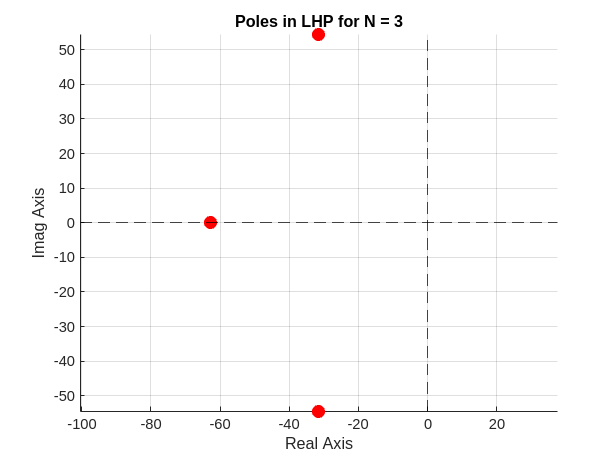

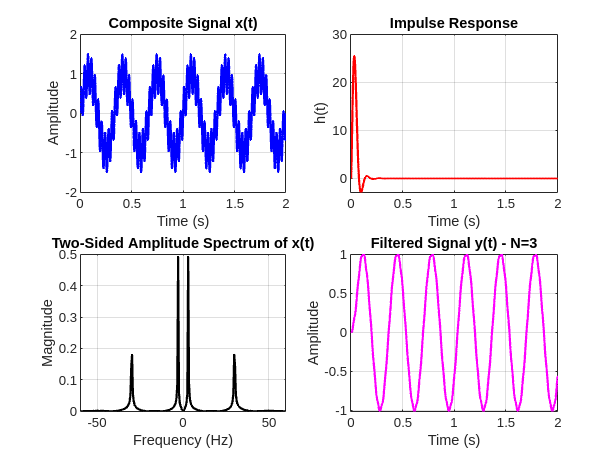

--- Butterworth Poles (N = 4) ---


Pole 1: Real=-24.0447, Imag=58.0491
Pole 2: Real=-58.0491, Imag=24.0447
Pole 3: Real=-58.0491, Imag=-24.0447
Pole 4: Real=-24.0447, Imag=-58.0491


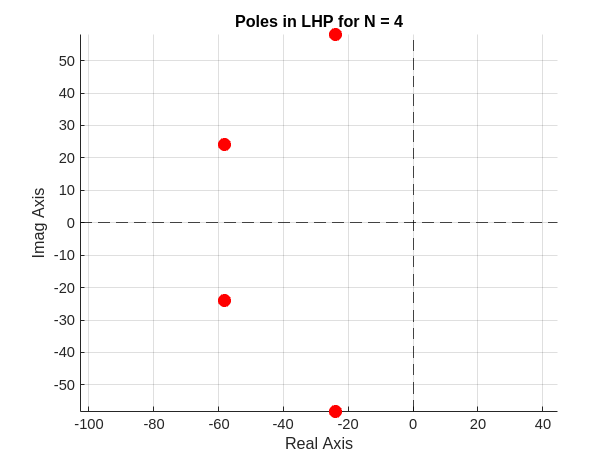

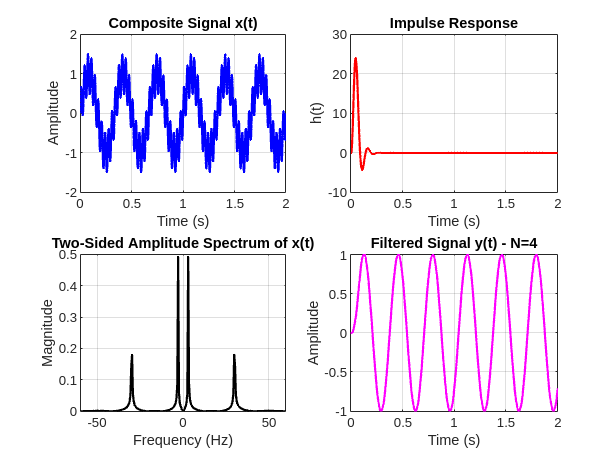

--- Butterworth Poles (N = 5) ---


Pole 1: Real=-19.4161, Imag=59.7566
Pole 2: Real=-50.832, Imag=36.9316
Pole 3: Real=-62.8319, Imag=7.6947e-15
Pole 4: Real=-50.832, Imag=-36.9316
Pole 5: Real=-19.4161, Imag=-59.7566


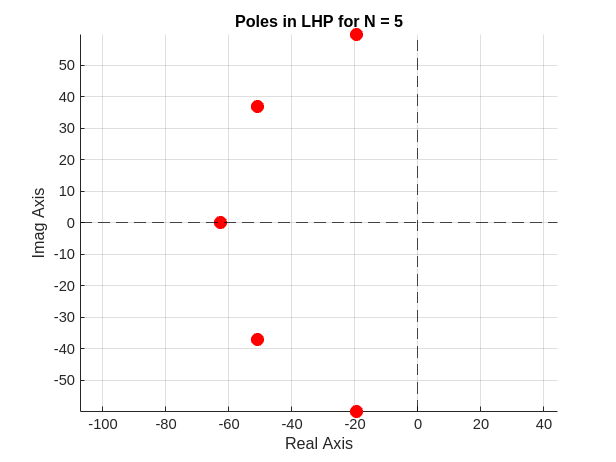

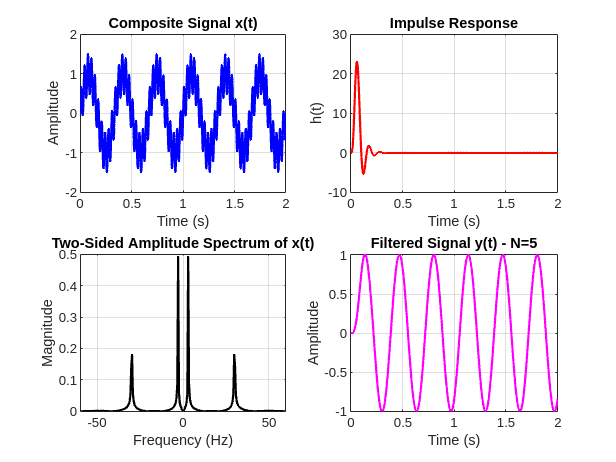

--- Butterworth Poles (N = 6) ---


Pole 1: Real=-16.2621, Imag=60.6909
Pole 2: Real=-44.4288, Imag=44.4288
Pole 3: Real=-60.6909, Imag=16.2621
Pole 4: Real=-60.6909, Imag=-16.2621
Pole 5: Real=-44.4288, Imag=-44.4288
Pole 6: Real=-16.2621, Imag=-60.6909


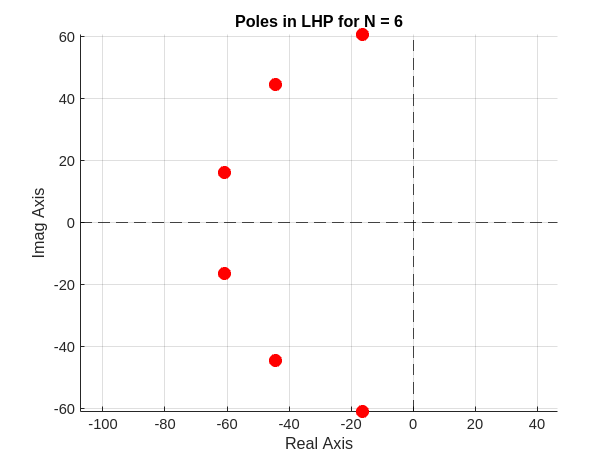

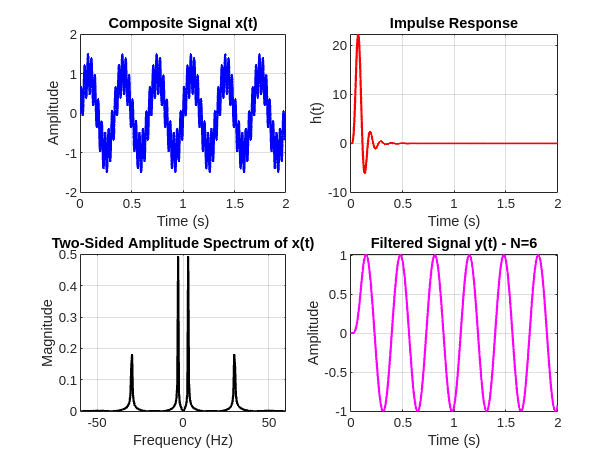

--- Butterworth Poles (N = 7) ---


Pole 1: Real=-13.9814, Imag=61.2565
Pole 2: Real=-39.175, Imag=49.1239
Pole 3: Real=-56.6095, Imag=27.2617
Pole 4: Real=-62.8319, Imag=7.6947e-15
Pole 5: Real=-56.6095, Imag=-27.2617
Pole 6: Real=-39.175, Imag=-49.1239
Pole 7: Real=-13.9814, Imag=-61.2565


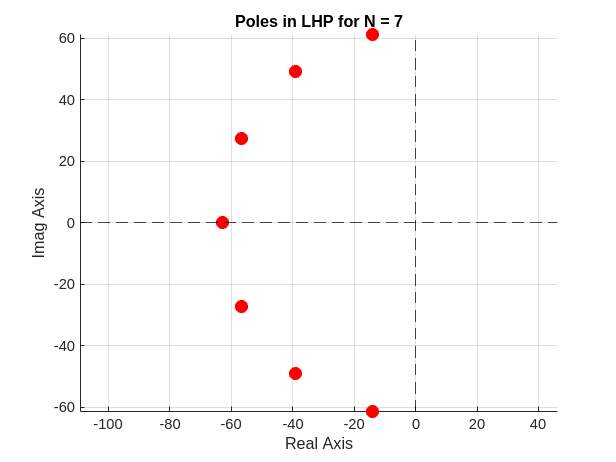

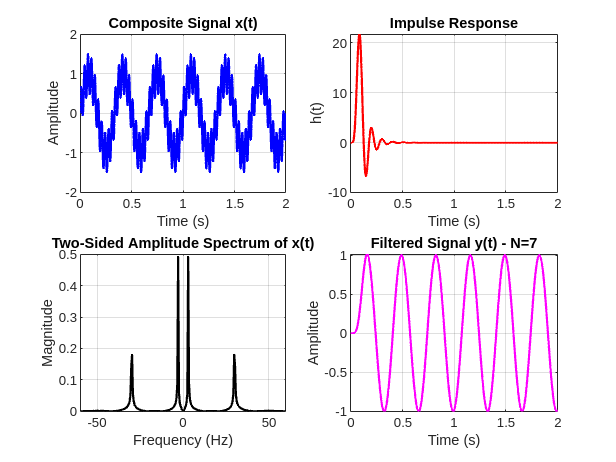

--- Butterworth Poles (N = 11) ---


Pole 1: Real=-8.9419, Imag=62.1923
Pole 2: Real=-26.1013, Imag=57.1539
Pole 3: Real=-41.1461, Imag=47.4851
Pole 4: Real=-52.8575, Imag=33.9695
Pole 5: Real=-60.2867, Imag=17.7018
Pole 6: Real=-62.8319, Imag=7.6947e-15
Pole 7: Real=-60.2867, Imag=-17.7018
Pole 8: Real=-52.8575, Imag=-33.9695
Pole 9: Real=-41.1461, Imag=-47.4851
Pole 10: Real=-26.1013, Imag=-57.1539
Pole 11: Real=-8.9419, Imag=-62.1923


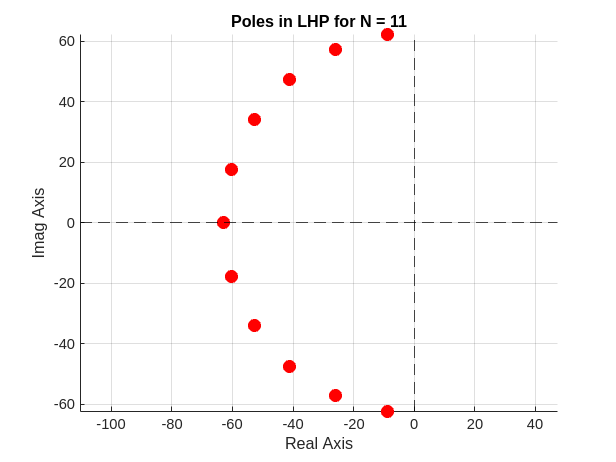

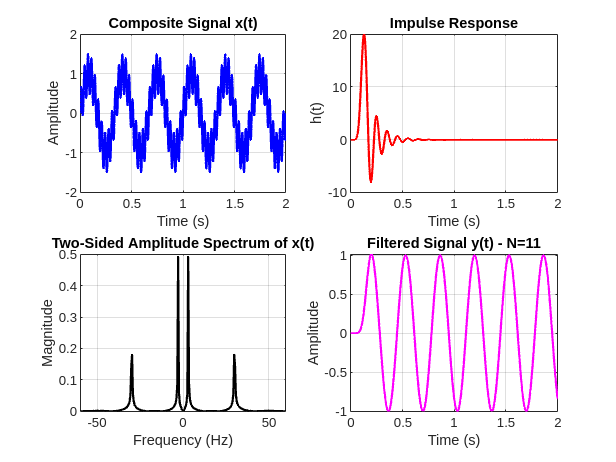


clear; close all; clc;

fc    = 10;      
omgc  = 2*pi*fc;  
T_end = 2;        
dt    = 1e-3;    
t     = 0:dt:T_end;

fs    = 1/dt;
Nt    = length(t);

x = sin(2*pi*3*t) + 0.5*sin(2*pi*30*t);
Nfft   = 2^nextpow2(Nt);   
X_fft  = fft(x, Nfft);      
X_shifted = fftshift(X_fft);
X_mag_2sided = abs(X_shifted)/Nt; 
f_axis_2sided = (-Nfft/2 : Nfft/2-1) * (fs/Nfft);

N_values = [3, 4, 5, 6, 7, 11];

for idx = 1:length(N_values)
    N_order = N_values(idx);
    k = 1:N_order;
    allPoles = omgc * exp(1i*(pi/2 + (2*k - 1)*pi/(2*N_order)));
    LHP_poles = allPoles(real(allPoles) < 0);
    if length(LHP_poles) ~= N_order
        warning(['Expected ' num2str(N_order) ...
                 ' LHP poles but found ' num2str(length(LHP_poles)) '.']);
    end

    disp(['--- Butterworth Poles (N = ' num2str(N_order) ') ---']);
    for p_idx = 1:length(LHP_poles)
        p_val = LHP_poles(p_idx);
        disp(['Pole ' num2str(p_idx) ': Real=' num2str(real(p_val)) ...
              ', Imag=' num2str(imag(p_val))]);
    end

    figure('Name',['Butterworth Poles (N=', num2str(N_order),')'],'NumberTitle','off');
    scatter(real(LHP_poles), imag(LHP_poles), 80, 'r', 'filled');
    hold on; grid on; axis equal;
    xline(0, '--k'); yline(0, '--k');
    xlabel('Real Axis'); ylabel('Imag Axis');
    title(['Poles in LHP for N = ', num2str(N_order)]);
    denom = poly(LHP_poles);    
    denom = real(denom);        
    numer = omgc^N_order;      
    sys   = tf(numer, denom);  
    [h, t_imp] = impulse(sys, t); 
    y = lsim(sys, x, t);
    figure('Name',['Task 3: Butterworth LPF (N=', num2str(N_order),')'], ...
           'NumberTitle','off');

    subplot(2,2,1);
    plot(t, x, 'b', 'LineWidth',1.5);
    grid on; xlabel('Time (s)'); ylabel('Amplitude');
    title('Composite Signal x(t)');

    subplot(2,2,2);
    plot(t_imp, h, 'r', 'LineWidth',1.5);
    grid on; xlabel('Time (s)'); ylabel('h(t)');
    title('Impulse Response');

    subplot(2,2,3);
    plot(f_axis_2sided, X_mag_2sided, 'k', 'LineWidth',1.5);
    grid on; xlabel('Frequency (Hz)'); ylabel('Magnitude');
    title('Two-Sided Amplitude Spectrum of x(t)');
    xlim([-60 60]);

    subplot(2,2,4);
    plot(t, y, 'm', 'LineWidth',1.5);
    grid on; xlabel('Time (s)'); ylabel('Amplitude');
    title(['Filtered Signal y(t) - N=' num2str(N_order)]);
end


disp('All Butterworth LPF experiments complete!');

All Butterworth LPF experiments complete!


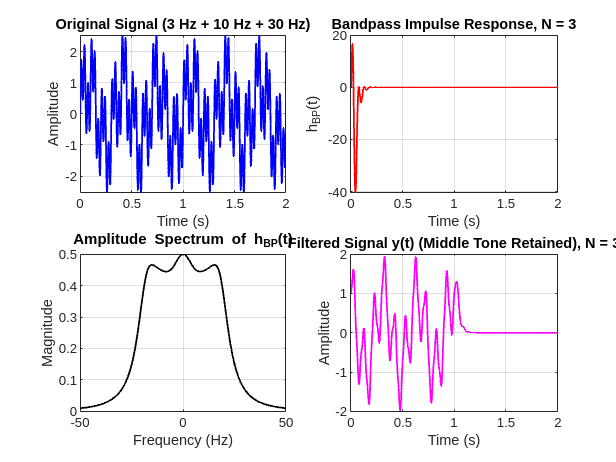

Task 4: Experiment complete for N = 3


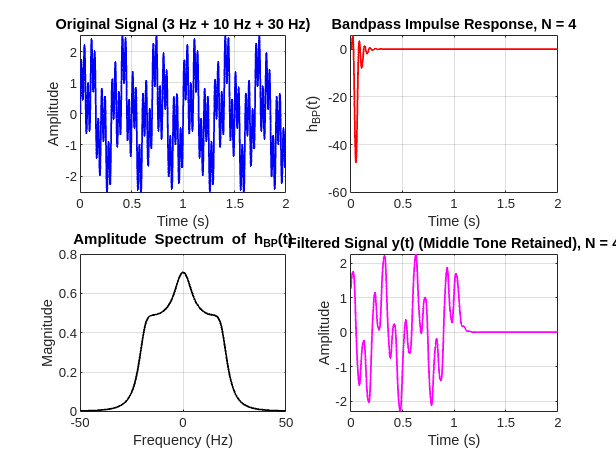

Task 4: Experiment complete for N = 4


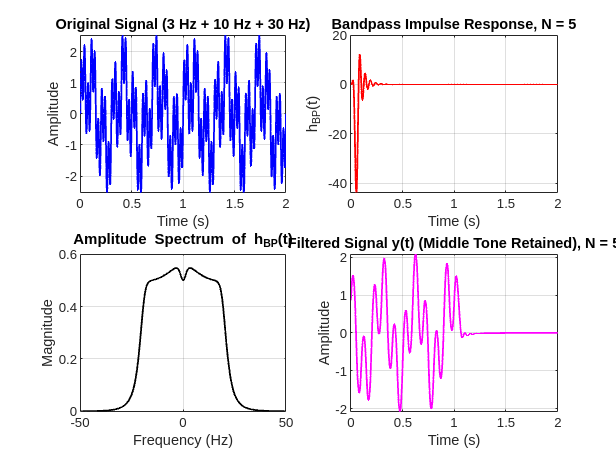

Task 4: Experiment complete for N = 5


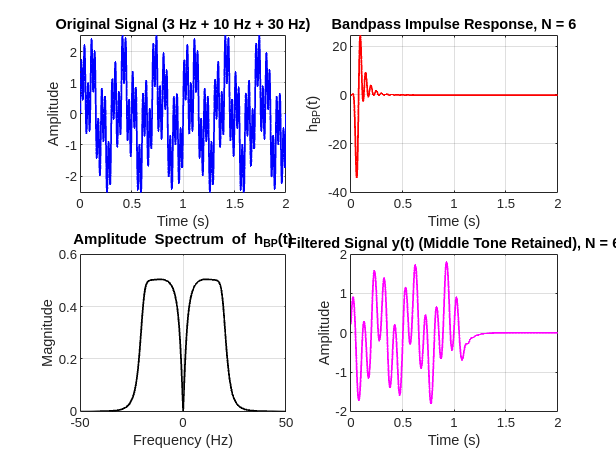

Task 4: Experiment complete for N = 6


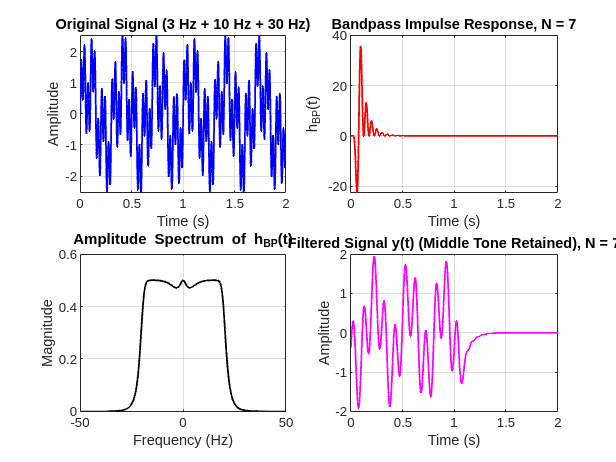

Task 4: Experiment complete for N = 7



clear; close all; clc;

fc    = 10;             
omgc  = 2*pi*fc;       
f_mid = 10;             
omega_mid = 2*pi*f_mid; 

T_end = 2;              
dt    = 1e-3;           
t     = 0:dt:T_end;     

fs = 1/dt;             
x = sin(2*pi*3*t) + sin(2*pi*10*t) + sin(2*pi*30*t);
N_values = [3, 4, 5, 6, 7];

for idx = 1:length(N_values)
    N = N_values(idx);
    k_vec = 1:N;
    poles_lp = omgc * exp(1i*(pi/2 + (2*k_vec - 1)*pi/(2*N)));
    denom_lp = poly(poles_lp);
    denom_lp = real(denom_lp); 
    gain_lp = omgc^N;          
    sys_lp = tf(gain_lp, denom_lp);
    [h_lp, t_imp] = impulse(sys_lp, t);
    h_bp = 2 * h_lp .* cos(omega_mid * t_imp);
    y = conv(x, h_bp, 'same') * dt;  
    Nfft = 2^nextpow2(length(h_bp));
    Hbp_fft = fft(h_bp, Nfft);
    Hbp_fft_shifted = fftshift(Hbp_fft);
    f_axis = (-Nfft/2:Nfft/2-1) * (fs/Nfft);
    Hbp_mag = abs(Hbp_fft_shifted) / length(h_bp);
    figure('Name',['Task 4: Bandpass Filter Experiment, N = ', num2str(N)], 'NumberTitle','off');
    
    subplot(2,2,1);
    plot(t, x, 'b', 'LineWidth',1.2);
    grid on;
    xlabel('Time (s)'); ylabel('Amplitude');
    title('Original Signal (3 Hz + 10 Hz + 30 Hz)');
    
    subplot(2,2,2);
    plot(t_imp, h_bp, 'r', 'LineWidth',1.2);
    grid on;
    xlabel('Time (s)'); ylabel('h_{BP}(t)');
    title(['Bandpass Impulse Response, N = ', num2str(N)]);
    
    subplot(2,2,3);
    plot(f_axis, Hbp_mag, 'k', 'LineWidth',1.2);
    grid on;
    xlabel('Frequency (Hz)'); ylabel('Magnitude');
    title('Amplitude Spectrum of h_{BP}(t)');
    xlim([-50 50]); 
    
    subplot(2,2,4);
    plot(t, y, 'm', 'LineWidth',1.2);
    grid on;
    xlabel('Time (s)'); ylabel('Amplitude');
    title(['Filtered Signal y(t) (Middle Tone Retained), N = ', num2str(N)]);
    
    disp(['Task 4: Experiment complete for N = ' num2str(N)]);
end


disp('All experiments for Task 4 complete!');

All experiments for Task 4 complete!
